# Building modelling for Anatomy

%Assumptions
SpaceTypes = ["Office/Study", "Laboratory", "Utility", "Toilets", "Corridor","Lecture Theatre"];
Values = ["SpaceOccupancy","ElectricalLoad","SupVentLoad","ExtractVentLoad","HeatingLoad","CoolingLoad"];

%https://www.engineeringtoolbox.com/number-persons-buildings-d_118.html
%BSRIA
data = [ 10 92 10 5 87 87;%Office/Study
    5 233 10 10 100 150;%Lab
    5 17 0 0 0 0;%Utility
    5 50 0 15 50 0;%Toilet
    10 17 0 0 0 0;%Corridor
    0.6 55 10 0 87 87];%Lecture Theatre


AssumptionsTable = array2table(data,'RowNames',string(SpaceTypes),'VariableNames',string(Values));

RefrigerationElectricalSpikeLoad = 5;
MedicalEquipmentElectricalSpikeLoad = 40;

%BSRIA - w/m^2
PeopleInternalHeatGain = 12;
EquipmentInternalHeatGain = 10;
SolarInternalHeatGain = 40;%W/m^2 - Only apply to 25% of Office/Study

% Occupancy Calcs

startDate = datetime('2024-01-01');
endDate = datetime('2024-12-31');
dates = startDate:endDate;

% Get full day names
dayNames = string(day(dates, 'name')); % 'dddd' gives full day names

% Create time strings (optional, if needed for another purpose)
times = hours(0:23);
timeStrings = string(datetime(2024,1,1) + times, 'HH:mm');  % Create datetime starting from a base date

% Preallocate the VarNames cell array
VarNames = cell(1, length(dates));

% Loop through each date and create formatted strings
for i = 1:length(dates)
    VarNames{i} = sprintf('%s: %s', datestr(dates(i), 'dd-mmm-yyyy'), dayNames(i));
end

%% Occupancy Matrix Setup

data = zeros(length(times),length(dates));

%% Assigning Occupancy based upon building used by:
% https://centaur.reading.ac.uk/108698/1/Identifying%20occupancy%20patterns%20and%20profiles%20in%20higher%20education%20institution%20buildings%20with%20high%20occupancy%20density%20A%20case%20study.pdf

%Occupancy percentage as
ASHRAEWorkday = [0 0 0 0 0 0 10 20 95 95 95 95 50 95 95 95 95 30 10 10 10 10 5 5];
ASHRAESaturday = [0 0 0 0 0 0 10 10 30 30 30 30 10 10 10 10 10 5 0 0 0 0 0 0];
ASHRAESunday = [0 0 0 0 0 0 5 5 5 5 5 5 5 5 5 5 5 5 5 0 0 0 0 0];

%Specifying Term Dates
AllStudentsAround = [datetime('2024-01-29'):datetime('2024-03-17'),datetime('2024-05-06'):datetime('2024-05-12'),datetime('2024-09-30'):datetime('2024-12-08')];
StaffAndPostGrad = [datetime('2024-01-02'):datetime('2024-01-14'),datetime('2024-04-01'):datetime('2024-04-21'),datetime('2024-05-27'):datetime('2024-09-15')];
InBetweenAround = [datetime('2024-01-15'):datetime('2024-01-28'), ...
    datetime('2024-03-18'):datetime('2024-03-31'), ...
    datetime('2024-04-22'):datetime('2024-05-05'), ...
    datetime('2024-05-13'):datetime('2024-05-26'), ...
    datetime('2024-09-16'):datetime('2024-09-29'), ...
    datetime('2024-12-09'):datetime('2024-12-22')];

% When All Students around (i.e. ASHRAE)
StudAround = ismember(dates,AllStudentsAround);

% When inbetween full teaching etc.
InBetween = ismember(dates,InBetweenAround);
DivisionNums = linspace(1/4,1,14);
AscDes = 1;
Week = 0;

% When just staff + postdocs around (i.e. ASHRAE divided by ...)
StaffAround = ismember(dates,StaffAndPostGrad);

for i=1:length(dates)
    if StudAround(i) == 1
        if dayNames(i) == 'Saturday'
            data(:,i) =  ASHRAESaturday;
        elseif dayNames(i) == 'Sunday'
            data(:,i) =  ASHRAESunday;
        else
            data(:,i) =  ASHRAEWorkday;
        end
    elseif StaffAround(i) == 1
        if dayNames(i) == 'Saturday'
            data(:,i) =  ASHRAESaturday/8;
        elseif dayNames(i) == 'Sunday'
            data(:,i) =  ASHRAESunday/8;
        else
            data(:,i) =  ASHRAEWorkday/4;
        end
    elseif InBetween(i) == 1
        if dayNames(i) == 'Saturday'
            if AscDes == 1
                data(:,i) =  ASHRAESaturday.*DivisionNums(Week*7+6);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAESaturday.*DivisionNums(0*7+2);
                elseif Week == 0
                    data(:,i) =  ASHRAESaturday.*DivisionNums(1*7+2);
                end
            end
        elseif dayNames(i) == 'Sunday'
            if AscDes == 1
                data(:,i) =  ASHRAESunday.*DivisionNums(Week*7+7);
                if Week == 1
                    AscDes = 0;
                    Week = 0;
                elseif Week == 0
                    Week = 1;
                end
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAESunday.*DivisionNums(0*7+1);
                    AscDes = 1;
                    Week = 0;
                elseif Week == 0
                    data(:,i) =  ASHRAESunday.*DivisionNums(1*7+1);
                    Week = 1;
                end
            end
        elseif dayNames(i) == 'Monday'
            if AscDes == 1
                data(:,i) =  ASHRAEWorkday.*DivisionNums(Week*7+1);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(0*7+7);
                elseif Week == 0
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(1*7+7);
                end
            end
        elseif dayNames(i) == 'Tuesday'
            if AscDes == 1
                data(:,i) =  ASHRAEWorkday.*DivisionNums(Week*7+2);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(0*7+6);
                elseif Week == 0
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(1*7+6);
                end
            end
        elseif dayNames(i) == 'Wednesday'
            if AscDes == 1
                data(:,i) =  ASHRAEWorkday.*DivisionNums(Week*7+3);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(0*7+5);
                elseif Week == 0
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(1*7+5);
                end
            end
        elseif dayNames(i) == 'Thursday'
            if AscDes == 1
                data(:,i) =  ASHRAEWorkday.*DivisionNums(Week*7+4);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(0*7+4);
                elseif Week == 0
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(1*7+4);
                end
            end
        elseif dayNames(i) == 'Friday'
            if AscDes == 1
                data(:,i) =  ASHRAEWorkday.*DivisionNums(Week*7+5);
            elseif AscDes == 0
                if Week == 1
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(0*7+3);
                elseif Week == 0
                    data(:,i) =  ASHRAEWorkday.*DivisionNums(1*7+3);
                end
            end
        end
    end
end

OccupancyPercentage = array2table(data./100,'RowNames',string(timeStrings),'VariableNames',string(VarNames));

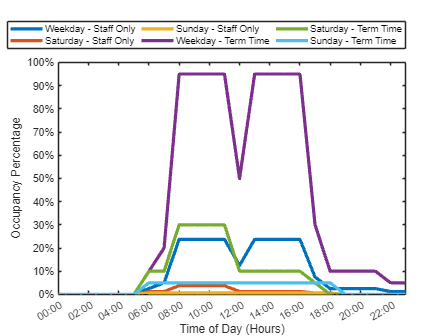

figure;

hold on
plot(OccupancyPercentage.("02-Jan-2024: Tuesday")*100,'LineWidth',3);
plot(OccupancyPercentage.("06-Jan-2024: Saturday")*100,'LineWidth',3);
plot(OccupancyPercentage.("07-Jan-2024: Sunday")*100,'LineWidth',3);

plot(OccupancyPercentage.("29-Jan-2024: Monday")*100,'LineWidth',3);
plot(OccupancyPercentage.("03-Feb-2024: Saturday")*100,'LineWidth',3);
plot(OccupancyPercentage.("04-Feb-2024: Sunday")*100,'LineWidth',3);
hold off
box on

legend(["Weekday - Staff Only","Saturday - Staff Only","Sunday - Staff Only","Weekday - Term Time","Saturday - Term Time","Sunday - Term Time"],'Location','northoutside','NumColumns',3)
%leg.Position = [0.7,0.8]
%fontsize(gca,24,"pixels");
ytickformat('percentage');
ylabel("Occupancy Percentage")%,FontSize=28)
xlabel("Time of Day (Hours)")%,FontSize=28)
xticks(1:2:length(OccupancyPercentage.Properties.RowNames));
xlim([1,24])
xticklabels(OccupancyPercentage.Properties.RowNames(1:2:end));

ax = gca;
exportgraphics(ax,'DailyOccupancy.eps','Resolution',300) 

% Monthly Occupancy Percentage
DailyAverageOccupancy = table2array(mean(OccupancyPercentage(7:24,:)));

% Step 1: Define the year
year = 2024;

% Step 2: Get months and number of days in each month
months = 1:12; % Months from January to December
daysInMonth = zeros(1, 12); % Initialize an array to hold the number of days

for m = months
    daysInMonth(m) = eomday(year, m); % Get the number of days in the month
end

% Step 3: Display the results
monthNames = month(datetime(year, months, 1), 'name'); % Get month names
index = 1;

MonthlyOccupancy = zeros(1, 12);

for i=1:length(months)
    PerMonthOccupancy = 0;
    for j=1:daysInMonth(i)
        PerMonthOccupancy = PerMonthOccupancy + DailyAverageOccupancy(index);
        index = index + 1;
    end
    MonthlyOccupancy(i) = PerMonthOccupancy/j;
end


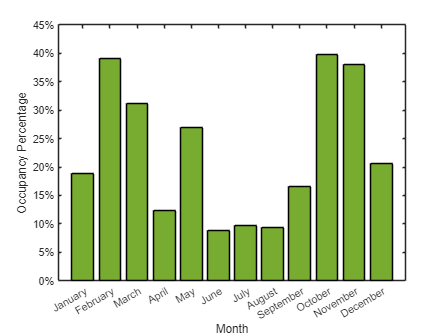


figure;
hold on
b = bar(monthNames,MonthlyOccupancy*100);
b.FaceColor = [0.4660 0.6740 0.1880];
%ytickformat('%,.0f');
hold off
box on

%legend("Monthly Occupancy Percentage");
%fontsize(gca,39,"pixels");
ytickformat('percentage');
ylabel("Occupancy Percentage")%,FontSize=42);
xlabel("Month")%,FontSize=42);
ylim([0,45])

ax = gca;
exportgraphics(ax,'MonthlyOccupancy.eps','Resolution',300) 

% Importing Useful Data
% Level, Room Number, Room Type, Area, Height

%% Import data from spreadsheet
% Script for importing data from the following spreadsheet:
%
%    Workbook: C:\Users\xh21734\OneDrive - University of Bristol\Year 4 Uni Work\Renewable Energy for a Sustainable Future\General - grp-Renewables\Modelling\BuildingValues.xlsx
%    Worksheet: Sheet1
%
% Auto-generated by MATLAB on 15-Oct-2024 12:00:57

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:E243";

% Specify column names and types
opts.VariableNames = ["Level", "Number", "SpaceType", "Area", "Height"];
opts.VariableTypes = ["categorical", "categorical", "categorical", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Level", "Number", "SpaceType"], "EmptyFieldRule", "auto");

% Import the data
BuildingValues = readtable("BuildingValues.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts

%Identifying locations of space types

OfficeStudySpaces = ismember(BuildingValues.SpaceType,SpaceTypes(1));
LabSpaces = ismember(BuildingValues.SpaceType,SpaceTypes(2));
UtilitySpaces = ismember(BuildingValues.SpaceType,SpaceTypes(3));
ToiletSpaces = ismember(BuildingValues.SpaceType,SpaceTypes(4));
CorridorSpaces = ismember(BuildingValues.SpaceType,SpaceTypes(5));
LecutreSpaces = ismember(BuildingValues.SpaceType,SpaceTypes(6));

All = {};
All(:,1) = cellstr(BuildingValues.Level);
All(:,2) = cellstr(BuildingValues.Number);
All(:,3) = cellstr(BuildingValues.SpaceType);
All(:,4) = num2cell(BuildingValues.Area);
All(:,5) = num2cell(BuildingValues.Height);

Occupancy = BuildingValues.Area ./ (OfficeStudySpaces*AssumptionsTable{"Office/Study","SpaceOccupancy"}...
    + LabSpaces*AssumptionsTable{"Laboratory","SpaceOccupancy"}...
    + UtilitySpaces*AssumptionsTable{"Utility","SpaceOccupancy"}...
    + ToiletSpaces*AssumptionsTable{"Toilets","SpaceOccupancy"}...
    + CorridorSpaces*AssumptionsTable{"Corridor","SpaceOccupancy"}...
    + LecutreSpaces*AssumptionsTable{"Lecture Theatre","SpaceOccupancy"}); %Value given as number of people per space

All(:,6) = num2cell(Occupancy);


for i=1:length(Occupancy)
    All(i,10) = {table2array(OccupancyPercentage).*Occupancy(i)};
end

mean(mean(table2array(OccupancyPercentage)))

ans = 0.1691


max(sum(cell2mat(All(:,10))))

ans = 1.3497e+04

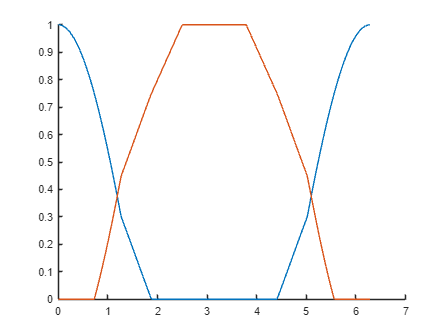

% Heating & Cooling Load Percentages
x = linspace(0,2*pi,length(dates));
HeatingLoadPercentage = cos(x);
for i=1:length(dates)
    if HeatingLoadPercentage(i) < 0.3
        HeatingLoadPercentage(i) = HeatingLoadPercentage(i) + 0.5*(0.3 - HeatingLoadPercentage(i));
    end
end

HeatingLoadPercentage(HeatingLoadPercentage < 0) = 0;
CoolingLoadPercentage = 0.75 - HeatingLoadPercentage;
indexes = find(CoolingLoadPercentage == 0.75);
CoolingLoadPercentage(indexes(1:length(indexes)/4)) = linspace(0.75, 1, length(indexes)/4);
CoolingLoadPercentage(indexes(length(indexes)/4:3*length(indexes)/4)) = 1 - HeatingLoadPercentage(indexes(length(indexes)/4:3*length(indexes)/4));
CoolingLoadPercentage(indexes(3*length(indexes)/4+1:length(indexes))) = linspace(1, 0.75, length(indexes)/4);
CoolingLoadPercentage(CoolingLoadPercentage < 0) = 0;



figure
hold on
plot(x,HeatingLoadPercentage);
plot(x,CoolingLoadPercentage);
hold off

% Heating Load

SpaceHeatingLoad = (BuildingValues.Area .* (OfficeStudySpaces*AssumptionsTable{"Office/Study","HeatingLoad"}...
    + LabSpaces*AssumptionsTable{"Laboratory","HeatingLoad"}...
    + UtilitySpaces*AssumptionsTable{"Utility","HeatingLoad"}...
    + ToiletSpaces*AssumptionsTable{"Toilets","HeatingLoad"}...
    + CorridorSpaces*AssumptionsTable{"Corridor","HeatingLoad"}...
    + LecutreSpaces*AssumptionsTable{"Lecture Theatre","HeatingLoad"} ...
    - OfficeStudySpaces*0.25*SolarInternalHeatGain ...
    - EquipmentInternalHeatGain) - Occupancy.*PeopleInternalHeatGain)./1000; %Value given in kWh

for i=1:length(SpaceHeatingLoad)
    All(i,7) = {table2array(OccupancyPercentage).*HeatingLoadPercentage.*SpaceHeatingLoad(i)};
end

DailyTotalHeating = sum(cell2mat(All(:,7)));
AnnualTotalHeating = sum(sum(cell2mat(All(:,7))));

% Cooling Load
SpaceCoolingLoad = (BuildingValues.Area .* (OfficeStudySpaces*AssumptionsTable{"Office/Study","CoolingLoad"}...
    + LabSpaces*AssumptionsTable{"Laboratory","CoolingLoad"}...
    + UtilitySpaces*AssumptionsTable{"Utility","CoolingLoad"}...
    + ToiletSpaces*AssumptionsTable{"Toilets","CoolingLoad"}...
    + CorridorSpaces*AssumptionsTable{"Corridor","CoolingLoad"}...
    + LecutreSpaces*AssumptionsTable{"Lecture Theatre","CoolingLoad"} ...
    + OfficeStudySpaces*0.25*SolarInternalHeatGain ...
    + EquipmentInternalHeatGain) + Occupancy.*PeopleInternalHeatGain)./1000; %Value given in kWh

for i=1:length(SpaceCoolingLoad)
    All(i,8) = {table2array(OccupancyPercentage).*CoolingLoadPercentage.*SpaceCoolingLoad(i)};
end

DailyTotalCooling = sum(cell2mat(All(:,8)));
AnnualTotalCooling = sum(sum(cell2mat(All(:,8))));

%% Electrical Load

SpaceElectricalLoad = BuildingValues.Area .* (OfficeStudySpaces*AssumptionsTable{"Office/Study","ElectricalLoad"}...
    + LabSpaces*AssumptionsTable{"Laboratory","ElectricalLoad"}...
    + UtilitySpaces*AssumptionsTable{"Utility","ElectricalLoad"}...
    + ToiletSpaces*AssumptionsTable{"Toilets","ElectricalLoad"}...
    + CorridorSpaces*AssumptionsTable{"Corridor","ElectricalLoad"}...
    + LecutreSpaces*AssumptionsTable{"Lecture Theatre","ElectricalLoad"})./1000; %Value given in kWh

ElectricalOccupancyPercentage = table2array(OccupancyPercentage);
ElectricalOccupancyPercentage(ElectricalOccupancyPercentage == 0) = 0.025;

for i=1:length(SpaceElectricalLoad)
    All(i,9) = {ElectricalOccupancyPercentage.*SpaceElectricalLoad(i)};%+RefrigerationElectricalSpikeLoad+MedicalEquipmentElectricalSpikeLoad)};
end

DailyTotalElectrical = sum(cell2mat(All(:,9)));
AnnualTotalElectrical = sum(sum(cell2mat(All(:,9))));

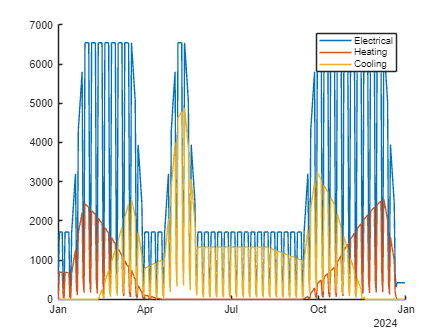

% Overall/Pretty Plots
figure;

hold on
plot(dates,DailyTotalElectrical)
plot(dates,DailyTotalHeating)
plot(dates,DailyTotalCooling)
hold off
legend(["Electrical","Heating","Cooling"])

% Exporting Important Values

HourlyHeatingLoad = zeros(length(times),length(dates));
HourlyCoolingLoad = zeros(length(times),length(dates));
HourlyElectricalLoad = zeros(length(times),length(dates));

for i=1:length(All(:,7))
    HourlyHeatingLoad = HourlyHeatingLoad + cell2mat(All(i,7));
    HourlyCoolingLoad = HourlyCoolingLoad + cell2mat(All(i,8));
    HourlyElectricalLoad = HourlyElectricalLoad + cell2mat(All(i,9));
end

HourlyHeatingLoad = array2table(HourlyHeatingLoad,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlyCoolingLoad = array2table(HourlyCoolingLoad,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlyElectricalLoad = array2table(HourlyElectricalLoad,'RowNames',string(timeStrings),'VariableNames',string(VarNames));

% Save specific variables a and b to a .mat file
save('../CurrentBuildingVariables.mat', 'HourlyHeatingLoad', 'HourlyCoolingLoad','HourlyElectricalLoad');

% Monthly Electrical Load

% Step 1: Define the year
year = 2024;

% Step 2: Get months and number of days in each month
months = 1:12; % Months from January to December
daysInMonth = zeros(1, 12); % Initialize an array to hold the number of days

for m = months
    daysInMonth(m) = eomday(year, m); % Get the number of days in the month
end

% Step 3: Display the results
monthNames = month(datetime(year, months, 1), 'name'); % Get month names
index = 1;

MonthlyElectricalLoads = zeros(1, 12);
MonthlyHeatingLoads = zeros(1, 12);
MonthlyCoolingLoads = zeros(1, 12);


for i=1:length(months)
    PerMonthElecLoad = 0;
    PerMonthHtgLoad = 0;
    PerMonthClgLoad = 0;
    for j=1:daysInMonth(i)
        PerMonthElecLoad = PerMonthElecLoad + DailyTotalElectrical(index);
        PerMonthHtgLoad = PerMonthHtgLoad + DailyTotalHeating(index);
        PerMonthClgLoad = PerMonthClgLoad + DailyTotalCooling(index);
        index = index + 1;
    end
    MonthlyElectricalLoads(i) = PerMonthElecLoad;
    MonthlyHeatingLoads(i) = PerMonthHtgLoad;
    MonthlyCoolingLoads(i) = PerMonthClgLoad;
end

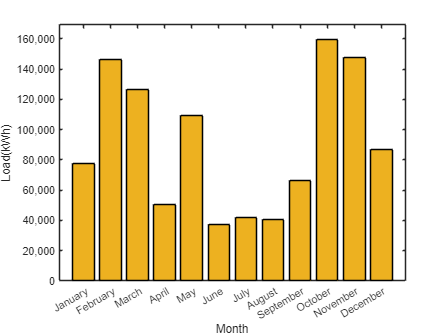


figure;
hold on
b = bar(monthNames,MonthlyElectricalLoads);
b.FaceColor = [0.9290 0.6940 0.1250];
ytickformat('%,.0f');
hold off
box on

%legend("Monthly Electrical Load");
%fontsize(gca,39,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ylim([0,max(MonthlyElectricalLoads,[],'all')+10000])
ytickformat('%,.0f');
ylabel("Load(kWh)")%,FontSize=42);
xlabel("Month")%,FontSize=42);

ax = gca;
exportgraphics(ax,'MonthlyElectricalLoad.eps','Resolution',300) 


%xticklabels(monthNames);

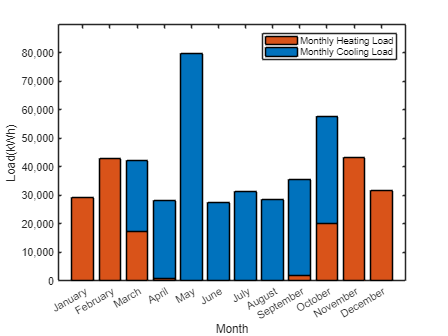

figure;
hold on
bar(monthNames,MonthlyCoolingLoads,'stacked');
bar(monthNames,MonthlyHeatingLoads,'stacked');
ytickformat('%,.0f');
hold off
box on

legend(["Monthly Cooling Load","Monthly Heating Load"]);
%fontsize(gca,39,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ylim([0,max(MonthlyCoolingLoads,[],'all')+10000])
ytickformat('%,.0f');
ylabel("Load(kWh)")%,FontSize=42);
xlabel("Month")%,FontSize=42);

ax = gca;
exportgraphics(ax,'MonthlyHtgClgLoad.eps','Resolution',300) 

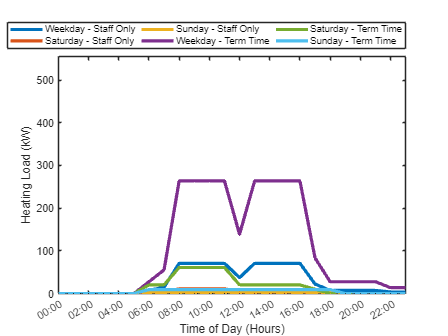

figure;

hold on
plot(HourlyHeatingLoad.("02-Jan-2024: Tuesday"),'LineWidth',3);
plot(HourlyHeatingLoad.("06-Jan-2024: Saturday"),'LineWidth',3);
plot(HourlyHeatingLoad.("07-Jan-2024: Sunday"),'LineWidth',3);

plot(HourlyHeatingLoad.("09-Dec-2024: Monday"),'LineWidth',3);
plot(HourlyHeatingLoad.("14-Dec-2024: Saturday"),'LineWidth',3);
plot(HourlyHeatingLoad.("15-Dec-2024: Sunday"),'LineWidth',3);
hold off
box on

legend(["Weekday - Staff Only","Saturday - Staff Only","Sunday - Staff Only","Weekday - Term Time","Saturday - Term Time","Sunday - Term Time"],'Location','northoutside','NumColumns',3)
%fontsize(gca,39,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f');
ylabel("Heating Load (kW)")%,FontSize=42)
xlabel("Time of Day (Hours)")%,FontSize=42)
ylim([0,table2array(max(HourlyCoolingLoad,[],'all'))+50])
xticks(1:2:length(HourlyHeatingLoad.Properties.RowNames));
xlim([1,24])
xticklabels(HourlyHeatingLoad.Properties.RowNames(1:2:end));


ax = gca;
exportgraphics(ax,'DailyHeating.eps','Resolution',300) 

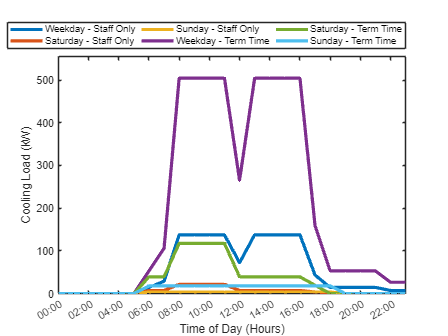

figure;

hold on
plot(HourlyCoolingLoad.("27-May-2024: Monday"),'LineWidth',3);
plot(HourlyCoolingLoad.("01-Jun-2024: Saturday"),'LineWidth',3);
plot(HourlyCoolingLoad.("02-Jun-2024: Sunday"),'LineWidth',3);

plot(HourlyCoolingLoad.("13-May-2024: Monday"),'LineWidth',3);
plot(HourlyCoolingLoad.("18-May-2024: Saturday"),'LineWidth',3);
plot(HourlyCoolingLoad.("19-May-2024: Sunday"),'LineWidth',3);

hold off
box on
ax = gca;
leg = legend(["Weekday - Staff Only","Saturday - Staff Only","Sunday - Staff Only","Weekday - Term Time","Saturday - Term Time","Sunday - Term Time"],'location','northoutside','NumColumns',3);
ax.YAxis.Exponent = 0;
ytickformat('%,.0f');
ylabel("Cooling Load (kW)")%,FontSize=42)
xlabel("Time of Day (Hours)")%,FontSize=42)
ylim([0,table2array(max(HourlyCoolingLoad,[],'all'))+50])
xticks(1:2:length(HourlyCoolingLoad.Properties.RowNames));
xlim([1,24])
xticklabels(HourlyCoolingLoad.Properties.RowNames(1:2:end));

exportgraphics(ax,'DailyCooling.eps','Resolution',300) 

% Internal Heat gains calc


cumsum = 0;

test = BuildingValues.Area .* OfficeStudySpaces*0.25*SolarInternalHeatGain./1000;

for i=1:length(test)
    cumsum = cumsum + sum(sum(table2array(OccupancyPercentage).*CoolingLoadPercentage.*test(i),1),2);
end